# An introduction to FPI

## Prof J. Morlier 

Fixed Point Iteration is a simple iterative method for solving systems of non-linear equations, such as the general two-equation non-linear system illustrated below: 				

f1(x1, x2) = 0 				

f2(x1, x2) = 0 				

This can be simplified using vector notation by writing f(x) = 0. The vectors in this notation could be of any size, as long as the size of the f and 0 vectors are equal. If the constituent equations are independent, i.e. no equation depends on the output of another equation, then the solution is trivial. In this case each equation may be solved independently. The case of non-independent equations (coupled) is more difficult. Consider the following example from [1]. 				

y21(y12) = 0.25*y12 − 0.25			

y12(y21) = 2 + 2*y21 			

This is special notation commonly used in coupled system analysis. The first function y21 depends on the output of the second function y12, and visa versa. The subscripts indicate the information flow. For example, y21 is the information generated by equation 1 that is required as input by equation 2 (2 ← 1). Note that although this example is linear, the method applied in this section is valid for non-linear systems. The interdependence, or coupling, between the two equations can be illustrated with a block diagram (Figure 1). 

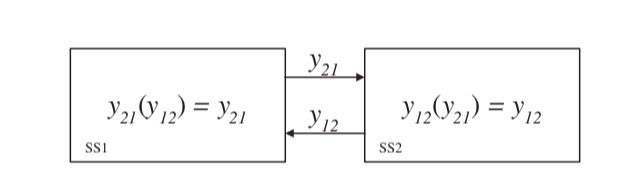

This shows the complete information flow of the system. 			

Remember that in a general non-linear system the constituent** functions may not be known explicitly, but are rather black box functions**. An intuitive approach to solving this system stems from the diagram of Figure 1. Make a guess for one of the values, say y21, and then use that value to calculate y12, which is in turn used to find an updated value of y21. This is repeated until the values stop changing, and is called the Fixed Point Iteration process. Here is the general algorithm:

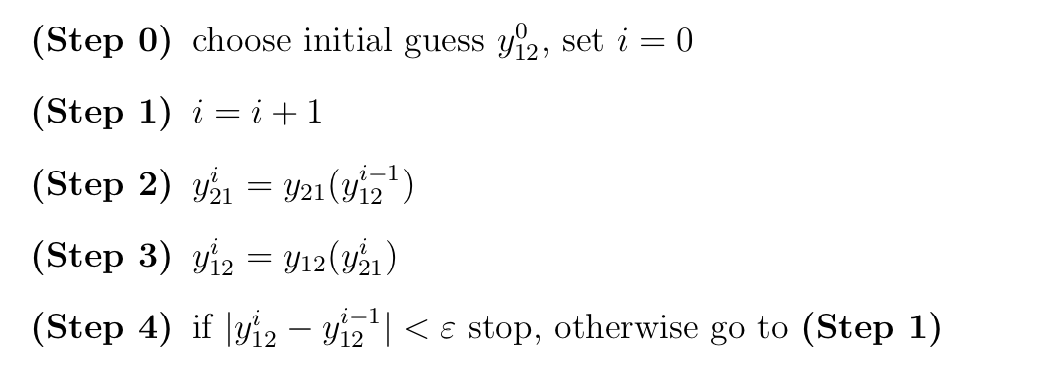

In the case of this simple example the solution can be viewed graphically. The functions y21 and y12 are plotted in Figure 2. The point where these functions cross is the solution to the system, also called a fixed point. 

				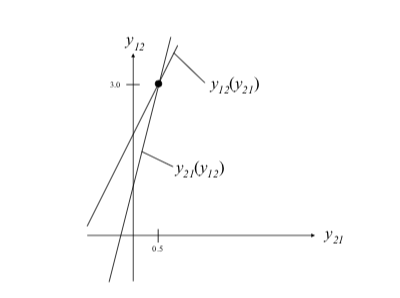

Let's try to do this !!				

Implementing the Fixed Point Iteration solution in Matlab requires the creation of two new functions and a script file to coordinate the functions. 

%clean up
clear all; close all;clc;		

One possible implementation is as follows:  

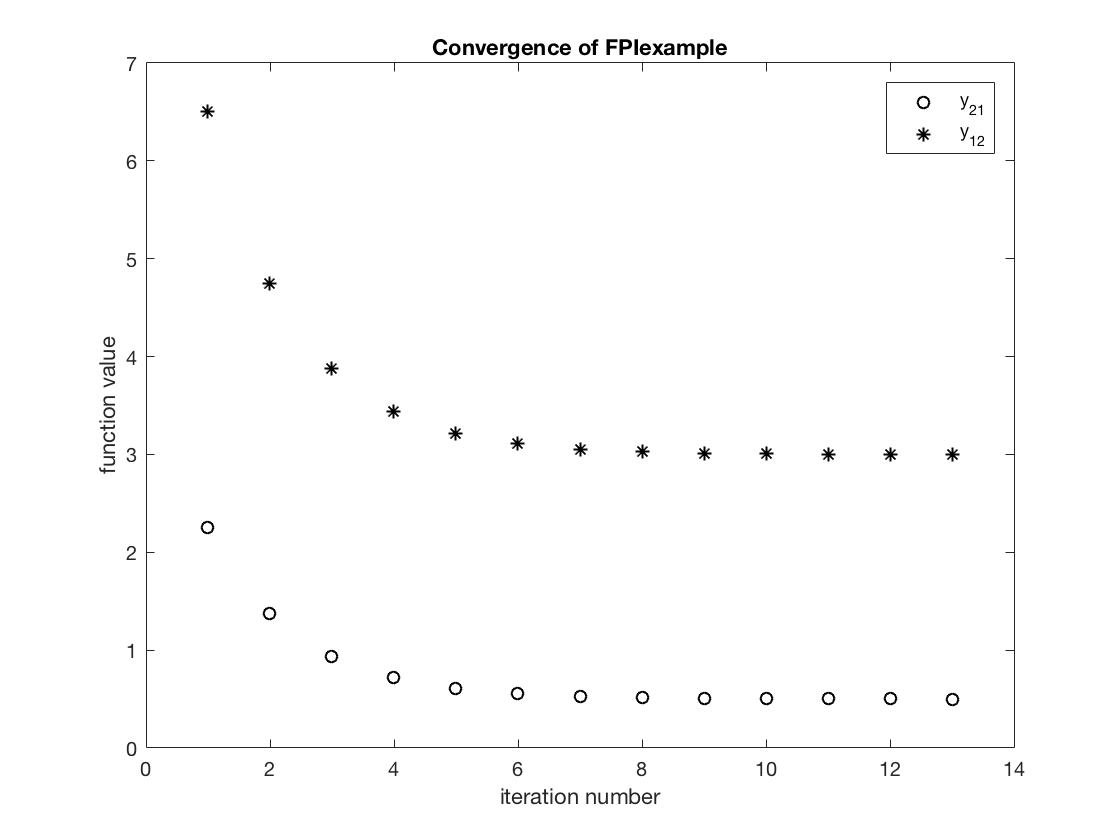

% initial guess
y12_old = 10;
% stopping criteria
epsilon = 1E-3;
% initialize parameters
error = 1E3; i = 1;
figure;
while error>epsilon
    y21_new = y21(y12_old);
    y12_new = y12(y21_new);
    plot(i,y21_new,'ko')
    hold on;
    plot(i,y12_new,'k*')
    i=i+1;
    error = abs(y12_new-y12_old);
    y12_old = y12_new;
   
    legend('y_{21}','y_{12}');
xlabel('iteration number')
ylabel('function value')
title('Convergence of FPIexample')
end

Remember that Gauss-Seidel approach are really efficient (see [2])This is a starting point for the NanoProject2.

References: 						

[1] James T. Allison, Introduction to Matlab CNS 3320 

[2] openMDAO.org